# Simulating sensors that have multiple pixel types and exposure times

*Developed by D. Cardinal, Stanford University, June, 2022*

*Initial target is Samsung's Corner Pixel Automotive technology*

In this script we compare traditional HDR bracketing (an equal number of stops above and below a base value), manual bracketing with arbitrary exposures, and a simulated "compund" sensor that records a single image based on the output from compound pixels that have two (or more) different photodetectors with different properties.

In the default case we simulate the compound pixel by allowing multiple exposures with different fill factors and exporure times.

For HDR rendering a shorter exposure time for the smaller photodector works well. Conversely, for LED flicker removal, a longer exposure time is needed.

ieInit();

% Select between a typical HDR scene, an extreme HDR scene,
% or our Chess Set scene rendered in 3d using pbrt-v4:
sceneType = 'pbrt'

sceneType = 'pbrt'


% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera();

% For Corner Pixel, we want an Auto-friendly sensor
% with larger main pixels than, for example, a smartphone
sensor = sensorFromFile('ar0132atSensorRGB.mat');

% for a larger sensor we need different optics
oi = oiCreate();
oi = oiSet(oi, 'optics', opticsCreate('standard (1-inch)'));

% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor and optics
ourCamera.cmodules(1) = cpCModule('sensor', sensor,'oi',oi);


#### Here are several example scenes to choose from:

ourSceneFile = fullfile('StuffedAnimals_tungsten-hdrs.mat');
extremeSceneFile = fullfile('Feng_Office-hdrs.mat');
hdrScene = cpScene('iset scene files', 'isetSceneFileNames', ourSceneFile);

Reading multispectral data with mcCOEF.
Saved using svd method


extremeScene = cpScene('iset scene files', 'isetSceneFileNames', extremeSceneFile);

Reading multispectral data with mcCOEF.
Saved using svd method



% We can also experiment with a 3D pbrt scene:
scenePath = 'ChessSet';
sceneName = 'chessSet';
numRays = 64; filmResolution = 512;
pbrtScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays);

Read 9 materials and 3 textures..


% put our scene in an interesting room
pbrtScene.thisR.set('skymap', 'room.exr', 'rotation val', [-90 0 0]);

% Choose which one of our example scenes to use
switch sceneType
    case 'Extreme'
        showScene = extremeScene;
        baseExposure = .3;
    case 'HDR'
        showScene = hdrScene;
        baseExposure = .1;
    case 'pbrt'
        showScene = pbrtScene;
        baseExposure = .2;
end

#### Baseline Images

As baseline images we capture an image of the scene using a camera set to full Auto mode, as well as one set to a traditional bracketing (HDR) mode..

Elapsed time is 0.860890 seconds.
Started Docker (status 0): docker  --context remote-mux run -d -it  --gpus device=0  --name pbrt-gpu-Windows14734  -v /home/david//iset/iset3d-v4/local/:/iset/iset3d-v4/local/  digitalprodev/pbrt-v4-gpu-ampere-mux-shared:latest bash
Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (1.82 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows14734 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 35.77 sec
Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d-v4/local/ChessSet/renderings ...
done (  1.94 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 43.3 sec ***

Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu

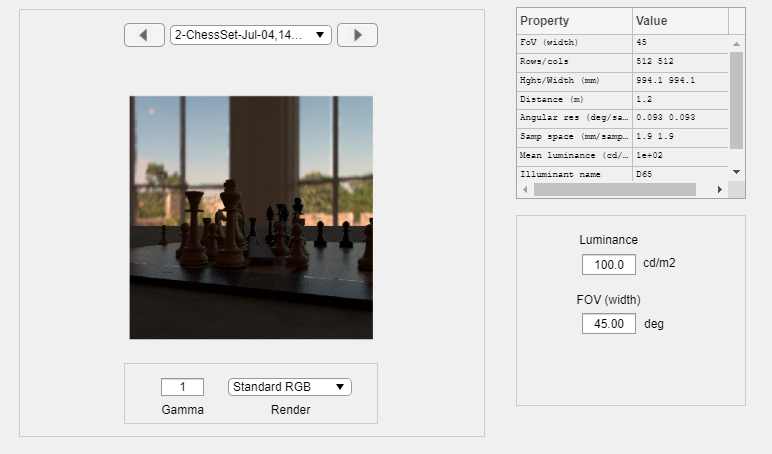

autoISETImage = ourCamera.TakePicture(showScene, 'Auto',...
    'imageName','ISET Scene in Auto Mode');

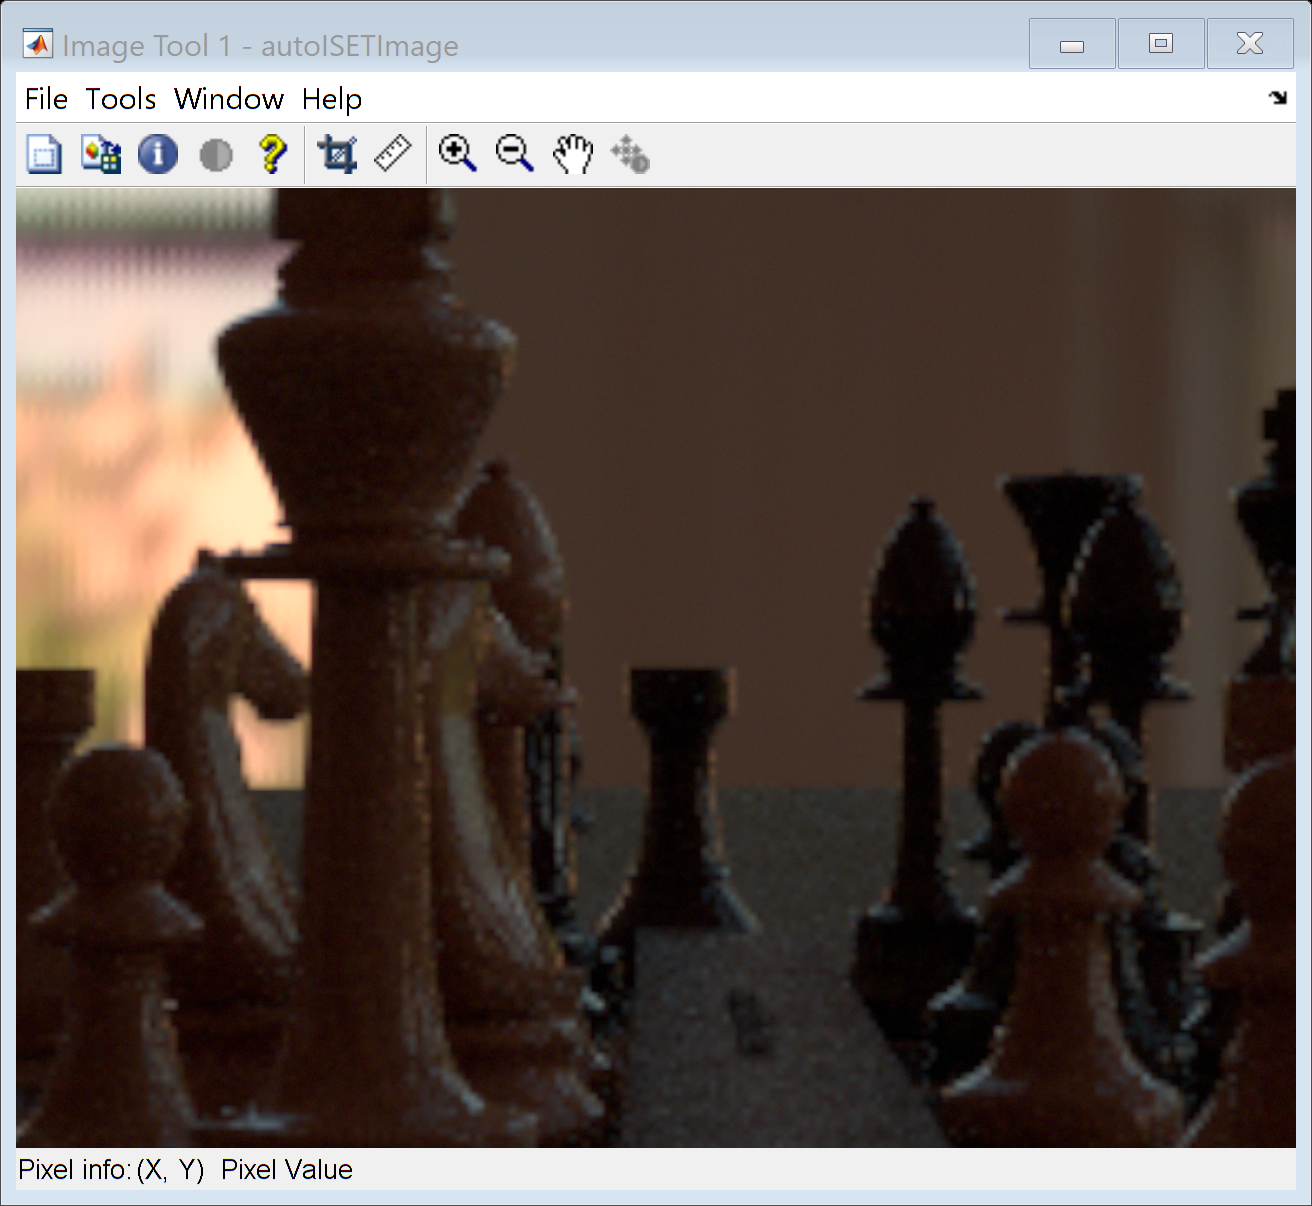

imtool(autoISETImage); 


% select whether to do 'simple' image combination
% in the sensor, or use a higher-level IP
insensorIP = true;
%
% Optional HDR baseline image
% Use a traditional HDR bracket (-1, 0, +1)
%{
hdrImage = ourCamera.TakePicture(showScene, 'HDR',...
    'insensorIP',insensorIP,'numHDRFrames',3,...
    'imageName',sprintf('HDR Mode with %d frames',3));
%}

#### Corner Pixel Simulation

Samgung's Corner Pixels start as a traditional Bayer array of pixels (typically large pixels for low-light scenes, around 3 microns). But "in the corners" between the large photosites are smaller ones, perhaps 1 micron -- in a matching Bayer array. The sensor can lengthen the exposure time on the small pixels to help alleviate LED flickering issues that are an issue when identifying traffic lights. Or shorten them to increase the dynamic range of the sensor.

We simulate the photodetector sizes by choosing fill factors, and placing any small photosites in the corner of the pixel.

Exposure times can also be altered. While Samsung only has 2 photodectors per pixel, we can simulate more if desired. 

One constraint of our model, and quite possibly real-world designs, is that we assume there is a single microlens over the entire pixel. So the smaller, included, photodetectors have the same microlens as the larger one.

#### Strategies for Improving Corner PIxel Designs

1) Higher Full-well capacity per surface area for smaller pixels?

2) Shorter shutter times for the smaller pixels?

Others?

Elapsed time is 0.891705 seconds.
Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (0.97 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows14734 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 4.73 sec
Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d-v4/local/ChessSet/renderings ...
done (  1.84 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 8.6 sec ***

Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (0.94 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows14734 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile rendering

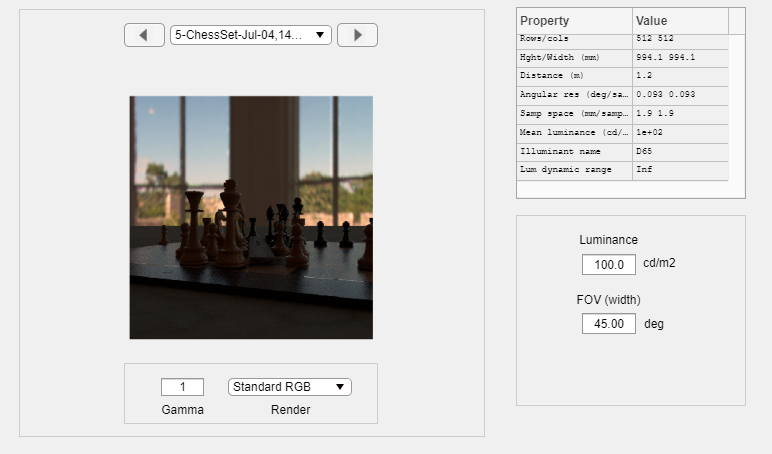

% right now we manually set exposure times for the Manual
% mode, so those need to be tweaked as needed
cornerFillFactors = [1.0 .11];

% shorter time for smaller pixels to help them preserve highlights.
cornerExpTimes = [baseExposure baseExposure/9];
cornerToneMap = 'longest';
cornerImage = ourCamera.TakePicture(showScene, 'Manual',...
    'insensorIP',insensorIP,'numHDRFrames',numel(cornerFillFactors),...
    'expTimes', cornerExpTimes, 'fillFactors', cornerFillFactors, ...
    'tonemap',cornerToneMap, ...
    'imageName','Corner Pixel Simulation');

#### Compare with Bracketed Images

Capture manual multi-exposures to compare with Corner Pixels. Key parameters are the exposure times and the tonemap parameter. Simple bracketed HDR uses "longest", where the longest non-saturated value is used. We also provide "largest" that simply looks for the largest raw value. 

For additional experimentation, you can set "inSensorIP to false, and work with code in the cpCamera's isp to do more sophisticated image combination (e.g. tonemapping).

% for modern Bayer sensors fill factor is usually >.8
% To keep our lives simpler, for comparison purposes we use 1
bracketFillFactors = [1 1 1];

Here you can play with how much you want to bracket. Traditional starts at -1, 0, +1, but for more extreme scenes or alternative approaches, you can vary the times and the number of exposures (if you change the number of exposure times, also make sure to change the number of fill factors to match.

Elapsed time is 0.777889 seconds.
Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (0.96 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows14734 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Rendered remotely in: 4.60 sec
Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d-v4/local/ChessSet/renderings ...
done (  1.93 sec)

Output file:  renderings/ChessSet.exr
*** Rendering time (ChessSet) was 8.5 sec ***

Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/ ...
Done (0.96 sec)
Command: docker --context remote-mux exec -i  pbrt-gpu-Windows14734 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile rendering

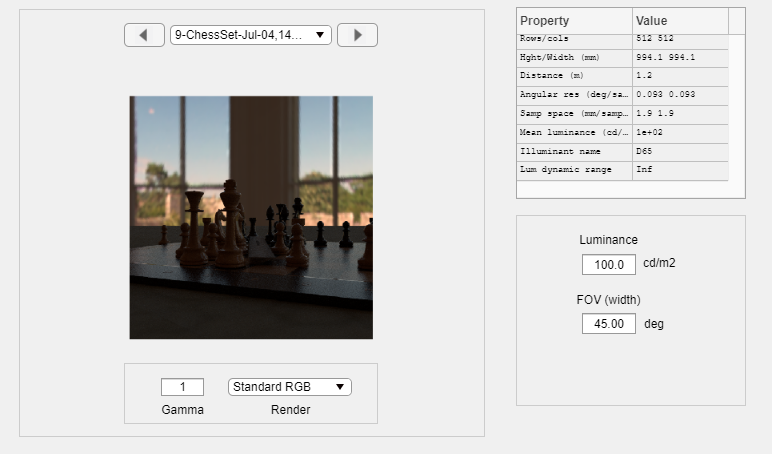

bracketExpTimes = [baseExposure baseExposure/3 baseExposure/9];

% Longest is simple, traditional tone mapping
% Largest is an interesting alternative that always selects
% the largest non-saturated value. Visual image quality suffers,
% but it might be an improvement for applications like Automotive.
bracketTonemap = 'longest';
bracketImage = ourCamera.TakePicture(showScene, 'Manual',...
    'insensorIP',insensorIP,'numHDRFrames',numel(bracketExpTimes),...
    'expTimes',bracketExpTimes, 'fillFactors',bracketFillFactors, ...
    'tonemap', bracketTonemap, ...
    'imageName','Manual Bracketing');

#### Visually compare our Results

Bracket: Fill= 1 1 1  Exp= 0.200 0.067 0.022 , EV: 0.200 0.067 0.022  
 Corner: Fill= 1, 0.11 & Exp= 0.200, 0.022, EV: 0.200 0.002 


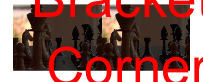

bracketFFormat = repmat('%s ', 1, numel(bracketFillFactors));
bracketEFormat = repmat('%2.3f ', 1, numel(bracketExpTimes));
bracketEVs = bracketFillFactors .* bracketExpTimes;
cornerEVs = cornerFillFactors .* cornerExpTimes;

caption = sprintf(['Bracket: Fill= ' bracketFFormat ' Exp= ' bracketEFormat ', EV: '...
    bracketEFormat ' \n', ...
    ' Corner: Fill= %s, %s & Exp= %2.3f, %2.3f, EV: %2.3f %2.3f'...
    ' \n'], ...
    string(bracketFillFactors), bracketExpTimes, bracketEVs, ...
    string(cornerFillFactors), cornerExpTimes, cornerEVs);
    
cpCompareImages(bracketImage,cornerImage,caption);

#### Analyze the Images

The previous comparison helps provide a visual comparison, but if we want to analyze the images we can bring them up in ipWindows.

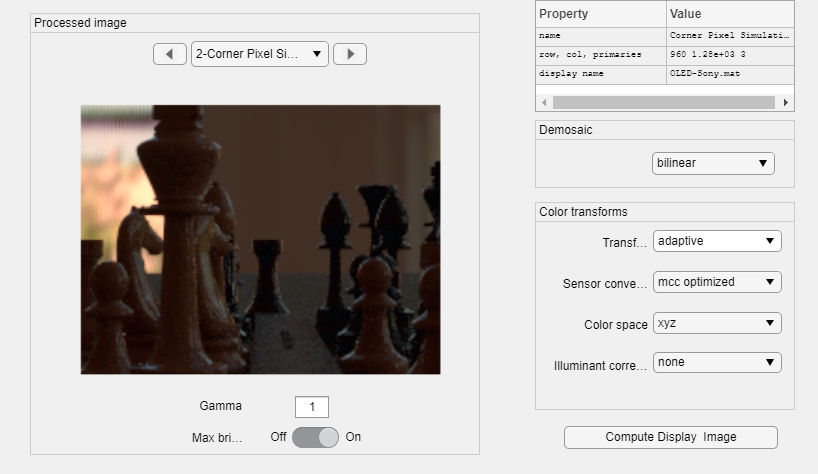

    ipWindow(bracketImage);
    ipWindow(cornerImage);

### Ideas for Further Work / Projects

How much does noise matter if the consumer is an ML system in a car?

What other tone map options might combine some of the advantages of "largest" and "longest"?